## Set up

clear;
close all;
cd '~/Repositories/densityDependentSelection/code'
import bioma.data.* 
% parameters for logistic growth
global param;

## Simulate in-vitro culture and passaging

This section uses the predicted r/K params for each subpopulation in a cell line to simulate in-vitro growth and re-plating. It requires a table ('allCPC') in data/subpopInfo that has columns 'r', 'K', and 'freq' representing the growth rate, carrying capacity, and relative frequency of each subpopulation. We use the locally defined function ODE_densityDependent to solve the coupled system of logistic growth functions for each cell line. 

% Import input data and set seeding size and passage times to test
cellLines = ["NCI-N87", "SNU-668"];
for l=1:2
    cellLine = cellLines(l);
    n=30; % number of passages to simulate
    if cellLine=="SNU-668"
        load('../data/subpopInfo/allCPC_SNU668_rK.mat');%object containing clonal frequencies and r/K params
        allCPC(6,:) = []; %remove 
        size_in=[5e03,2e04,5e04,1e05,2e05,3e05, 5e05,1e06, 2e06, 3e06]; %seed sizes to test
        topt_in=[1,2,2.5,3,3.5,5,6]; % passaging schedules to test
        index1=1; % position of clone1 in clone_sizes
        index2=3; % position of clone2 in clone_sizes
    elseif cellLine=="NCI-N87"
        load('../data/subpopInfo/allCPC_NCIN87_rK.mat'); %object containing clonal frequencies and r/K params
        allCPC(1,:) = [];
        size_in=[1e05,2e05,7e05,1e06, 2e06, 3e06, 5e06, 10e06, 15e06, 18e06];
        topt_in=[1,2,3,5,6,7,14];
        index1=2;
        index2=3;
    end

    % Set params
    growthrates = table2array(allCPC(:,'r'));
    carrycap = table2array(allCPC(:,'K'));
    clone_sizes = table2array(allCPC(:,'freq'));
    param = DataMatrix(ones(length(clone_sizes), 2), 'ColumnNames',{'r','K'});
    param(:,1) = growthrates;
    param(:,2) = carrycap;

    % Simulate one instance of clonal growth
    if cellLine=="NCI-N87"
    [Tn,Yn]=ode45(@ODE_densityDependent, [0 40], clone_sizes*1e05);
    strID=string(allCPC.Membership);
    end

    % Run simulations for all seed size-passage time combinations
    % For each seed size, we test all passaging schedules
    % For each passaging schedule, we simulate clonal growth across n passages
    % For both cell lines, we produce: 
    % 1. A plot simulating one instance of clonal growth a
    % 2. A heat map where entries represent the winning clone and size of winner
    % For NCI-N87 only, we produce:
    % 1. A plot showing the evolution of clones over passages 
    new_heatmap= [];
    for q=1:length(size_in) %iterating through seed sizes
        seed_size = size_in(q); %here seed size is set
        clone_sizes = clone_sizes/sum(clone_sizes);
        clone_sizes = clone_sizes.*seed_size;
        for z=1:length(topt_in) %iterating through passage schedules
            topt=topt_in(z);
            V2=cell(n,2);
            clone1 = double(0);
            clone2 = double(0);
            clone1(1) = clone_sizes(index1)/sum(clone_sizes);
            clone2(1) = clone_sizes(index2)/sum(clone_sizes);
            for i = 1:n %iterating through number of passages
                [T,Y]=ode45(@ODE_densityDependent, [0 topt], clone_sizes);
                clone1(i+1) = Y(end,index1)/sum(Y(end,:));
                clone2(i+1) = Y(end,index2)/sum(Y(end,:));
                clone_sizes = Y(end,:)/sum(Y(end,:));
                clone_sizes = clone_sizes.*seed_size;
            end           
            % for NCI-N87 only, we produce a plot showing clonal evolution
            % across passages for two seed_size-passage_schedule combinations
            if cellLine=="NCI-N87"
                if q==1 && z==6
                    clone1_save=clone1;
                    clone2_save=clone2;
                end
                if q==9 && z==1
                    clone1_save2=clone1;
                    clone2_save2=clone2;
                end
            end
            heatmaap = [seed_size, topt, sign(Y(end,index1)-Y(end,index2))*log10(max(Y(end,index1),Y(end,index2)))];
            new_heatmap= [new_heatmap; heatmaap];
            clone_sizes = table2array(allCPC(:,'freq'));
            clone_sizes = clone_sizes/sum(clone_sizes);
            clone_sizes = clone_sizes.*seed_size;
        end
    end

    % plot heat map
    in=array2table(new_heatmap);
    in.Properties.VariableNames(1) = "seed";
    in.Properties.VariableNames(2) = "split";
    in.Properties.VariableNames(3) = "freq";
    if cellLine=="NCI-N87"
        inNCI=in;
    elseif cellLine=="SNU-668"
        inSNU=in;
    end 
end

## Generate Figure 2D

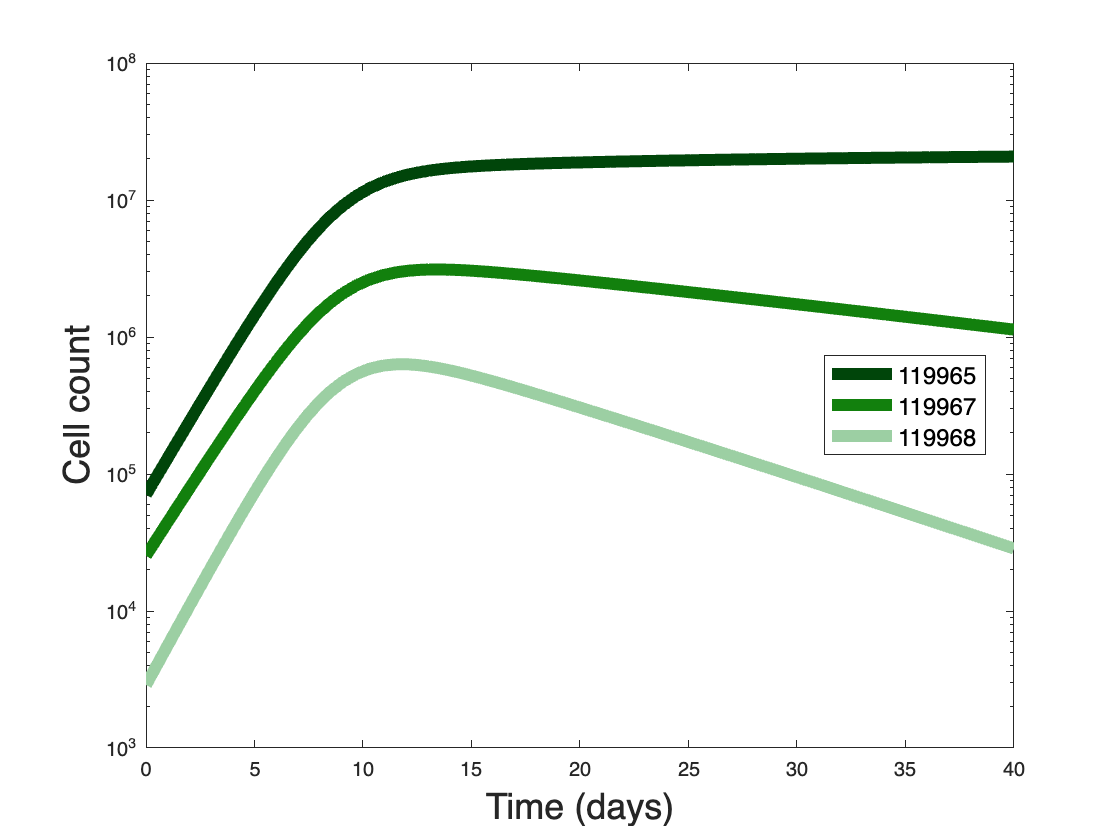

figure()
plot(Tn,Yn, 'LineWidth', 6)
colororder([0.00,0.27,0.04;0.07,0.50,0.05;0.61,0.81,0.64])
set(gca, 'YScale', 'log')
xlabel('Time (days)', 'FontSize',18)
ylabel('Cell count', 'FontSize',18)
legend(strID,'Location','Best', 'FontSize',12)

## Generate Figures 2B-C

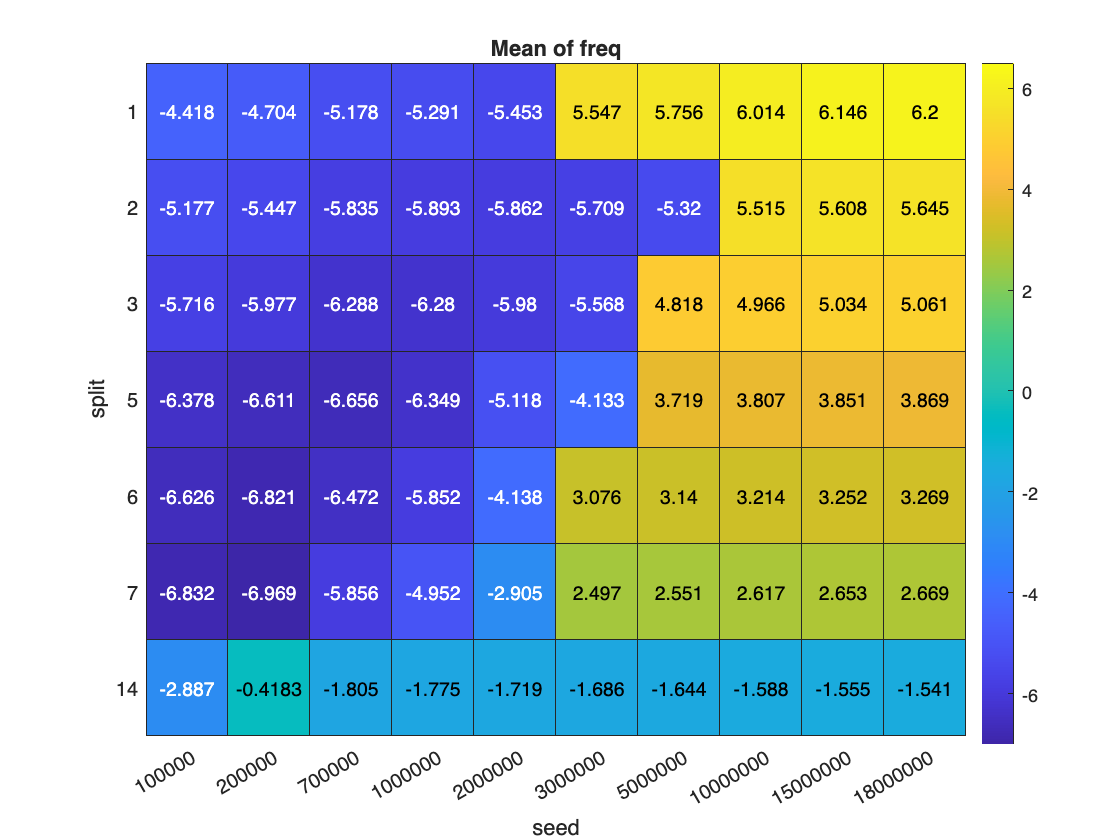

figure()
heatmap(inNCI,'seed','split','ColorVariable','freq')
clim([-7 6.5]);
colormap parula

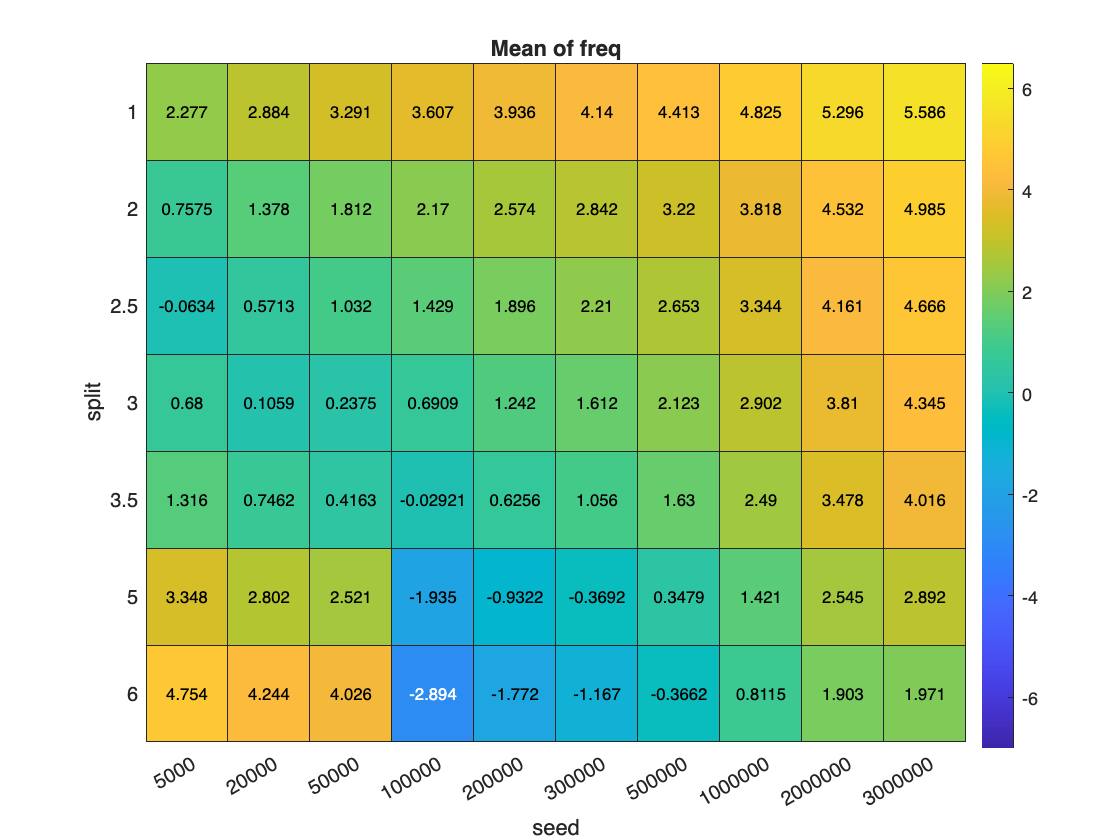

figure()
heatmap(inSNU,'seed','split','ColorVariable','freq')
clim([-7 6.5]);
colormap parula

## Generate Figure 2E

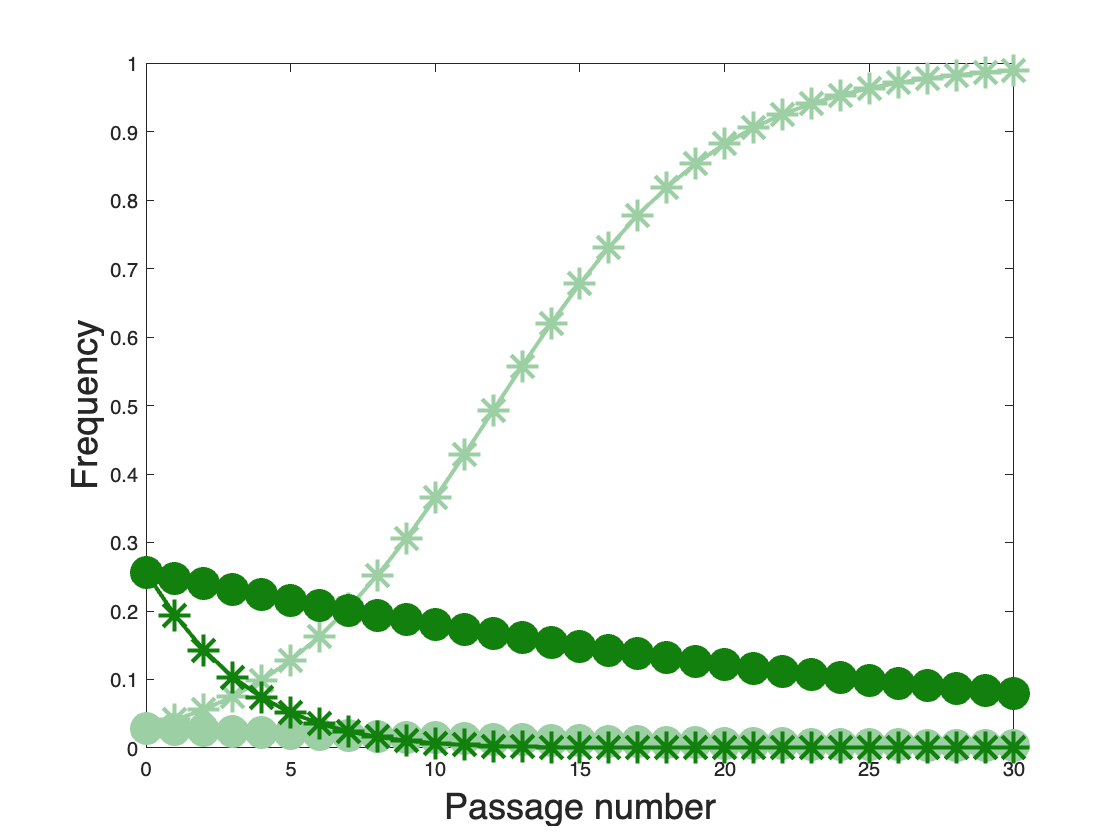

figure()
plot(0:30, clone2_save, '-*','LineWidth',2,'Color', [0.61,0.81,0.64], 'MarkerSize',16,'MarkerFaceColor', [0.61,0.81,0.64])
hold on
plot(0:30, clone2_save2, '--o', 'MarkerSize', 16, 'MarkerFaceColor', [0.61,0.81,0.64], 'MarkerEdgeColor', [0.61,0.81,0.64])
hold on
plot(0:30, clone1_save, '-*', 'LineWidth',2,'Color', [0.07,0.50,0.05], 'MarkerSize', 16, 'MarkerFaceColor', [0.07,0.50,0.05])
hold on
plot(0:30, clone1_save2, '--o', 'MarkerSize', 16, 'MarkerFaceColor', [0.07,0.50,0.05], 'MarkerEdgeColor', [0.07,0.50,0.05])
hold off
xlabel('Passage number', 'FontSize',18)
ylabel('Frequency', 'FontSize',18)

## Logistic function solver

function xdot = ODE_densityDependent(~,x)
% growth rate and carrying capacity
global param;
xdot = x;
for i = 1:length(x)
    xdot(i) = double(param(i,'r')) * x(i) * (1 - sum(x)/double(param(i,'K')));
end
end